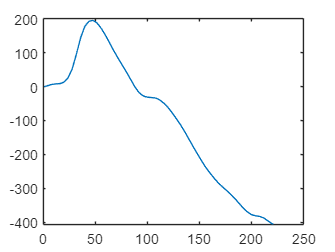

i1 = 3;
i2 = 3;
if (length(CYCLE_DATA_INH{i1}.RHEO2) > length(CYCLE_DATA_INH{i2}.RHEO2))
    data_temp1 = CYCLE_DATA_INH{i2}.RHEO2;
    data_temp2 = CYCLE_DATA_INH{i1}.RHEO2(1:length(CYCLE_DATA_INH{i2}.RHEO2));
else
    data_temp1 = CYCLE_DATA_INH{i1}.RHEO2;
    data_temp2 = CYCLE_DATA_INH{i2}.RHEO2(1:length(CYCLE_DATA_INH{i1}.RHEO2));
end
max(xcorr(data_temp1,data_temp2,'normalized'));
plot(-CYCLE_DATA_INH{i1}.RHEO1);

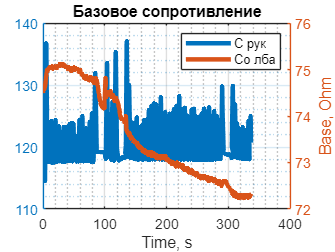

yyaxis left
plot(DATA.TIME,DATA.BASE1,'LineWidth',3);
yyaxis right
plot(DATA.TIME,DATA.BASE2,'LineWidth',3);
title("Базовое сопротивление")
legend(["С рук","Со лба"]);
ylabel('Base, Ohm') 
xlabel('Time, s')
grid on
grid minor

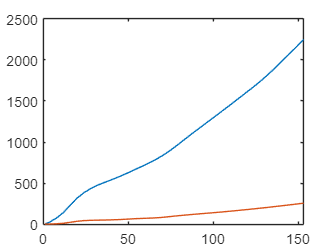

ii=3;
i1 = 1;
i2 = 4;
% if (length(CYCLE_DATA_EXH{i1}.RHEO2) > length(CYCLE_DATA_EXH{i2}.RHEO2))
%     data_temp1 = CYCLE_DATA_EXH{i2}.RHEO2;
%     data_temp2 = CYCLE_DATA_EXH{i1}.RHEO2(1:length(CYCLE_DATA_EXH{i2}.RHEO2));
% else
%     data_temp1 = CYCLE_DATA_EXH{i1}.RHEO2;
%     data_temp2 = CYCLE_DATA_EXH{i2}.RHEO2(1:length(CYCLE_DATA_EXH{i1}.RHEO2));
% end
% max(xcorr(data_temp1,data_temp2,'normalized'));
if (~isempty(FORM_EXH{ii}{i1}.RHEO1))
plot(-FORM_EXH{ii}{i1}.RHEO1);
hold on
plot(-FORM_EXH{ii}{i1}.RHEO2);
hold off
end

FORM_EXH{ii}{i1}.NAME

ans = datetime
   21-Nov-2024 11:17:00
